# Computer Assignment 6 - Signals & Systems - Dr  Akhavan

### **Question 1**

clc, clearvars, close all;

#### 1 - 1)

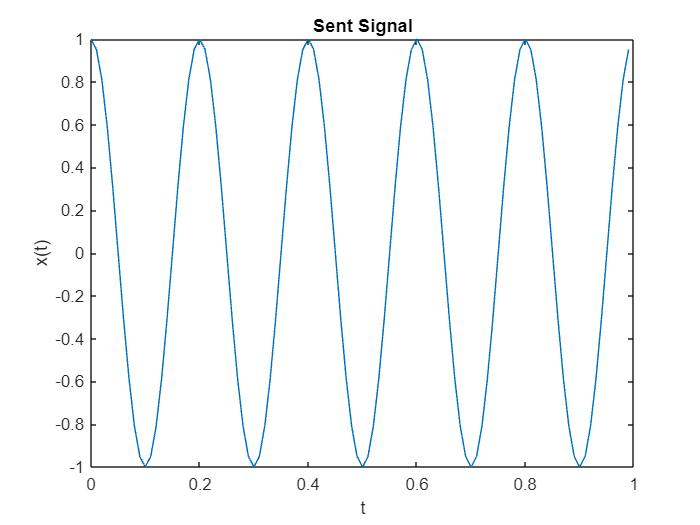

fc = 5;
fs = 100;
ts = 1 / fs;
tStart = 0;
tEnd = 1;
t = tStart : ts : tEnd - ts;
x = cos(2 * pi * fc * t);
plot(t, x);
xlabel('t'); ylabel('x(t)');
title("Sent Signal")

#### 1 - 2)

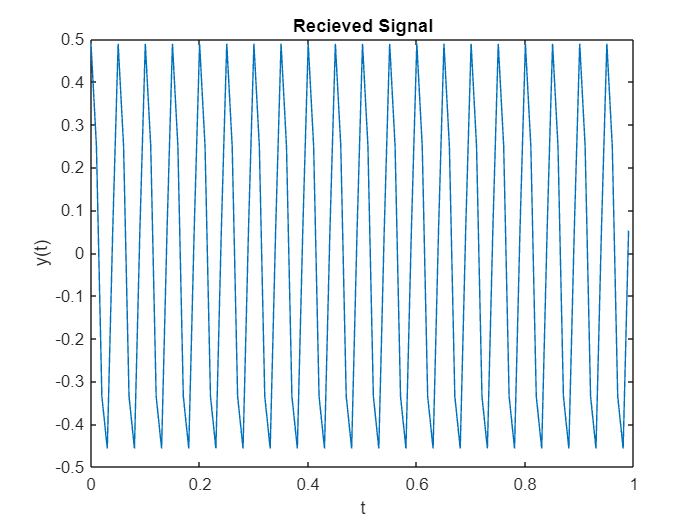

alpha = 0.5; beta = 0.3; C = 3e8;
R = 250 * 1e3 ; V = 180 * 1e3 / 3600;
ro = 2 / C; td = ro * R;
fd = beta * V;
YSum = alpha * cos(2 * pi * (fc + fd) * (t - td));
plot(t,YSum);
xlabel('t'); ylabel('y(t)');
title("Recieved Signal")

#### 1 - 3)

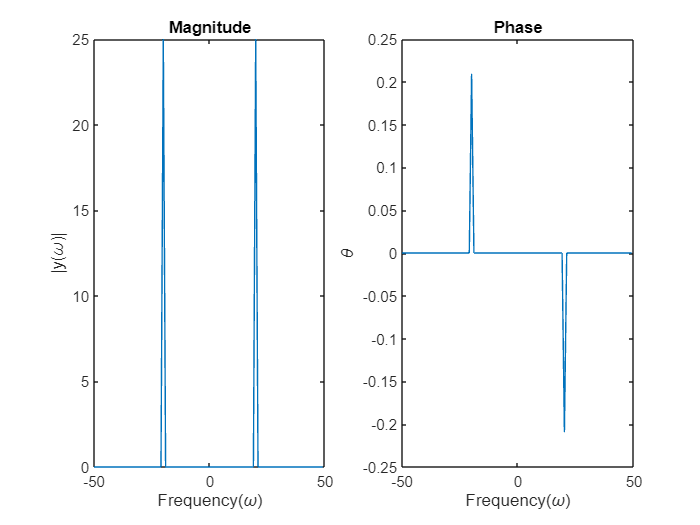

T = tEnd - tStart;
N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;
Y = fftshift(fft(YSum));
Y_magnitude = abs(Y);
figure;
subplot(1,2,1);
plot(f, abs(Y));
xlabel('Frequency(\omega)');ylabel('|y(\omega)|');
title("Magnitude");
threshold = 1e-6;
Y(abs(Y) < threshold) = 0;
Y_phase = angle(Y);
subplot(1,2,2);
plot(f, Y_phase);
xlabel('Frequency(\omega)')
ylabel('\theta')
title('Phase')

[~, maxIdx] = max(Y_magnitude);
fd = abs(f(maxIdx)) - fc

fd = 15

td = abs(Y_phase(maxIdx)) / (2 * pi * abs(f(maxIdx)))

td = 0.0017

#### 1 - 4)

times = 100;
fd_mean = 0;
td_mean = 0;
Rs_estimated = [];
Vs_estimated = [];
for std = 0:0.05:0.7
    fd_mean = 0;
    td_mean = 0;
    for i = 1:times
        yNoisy = std * randn(size(YSum)) + YSum;
        YNoisy = fftshift(fft(yNoisy));
        YNoisy_magnitude = abs(YNoisy);
        yNoisy_phase = angle(YNoisy);
        [~, maxIdx] = max(YNoisy_magnitude);
        fd = abs(f(maxIdx)) - fc;
        td = abs(yNoisy_phase(maxIdx)) / (2 * pi * abs(f(maxIdx)));
        fd_mean = fd_mean + fd / times;
        td_mean = td_mean + td / times;
    end
    V_estimated = fd_mean / beta;
    R_estimated = td_mean * C / 2;
    fprintf("std: %.2f, R: %.1f Km, V: %.1f m/s, V: %.1f Km/H \n", std, R_estimated / 1000, V_estimated, V_estimated * 3.6);
end

std: 0.00, R: 250.0 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.05, R: 248.8 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.10, R: 248.6 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.15, R: 246.2 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.20, R: 261.5 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.25, R: 250.6 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.30, R: 249.7 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.35, R: 232.3 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.40, R: 243.9 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.45, R: 258.3 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.50, R: 232.6 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.55, R: 251.8 Km, V: 50.0 m/s, V: 180.0 Km/H 
std: 0.60, R: NaN Km, V: 49.3 m/s, V: 177.6 Km/H 
std: 0.65, R: 312.1 Km, V: 51.0 m/s, V: 183.6 Km/H 
std: 0.70, R: 299.8 Km, V: 50.8 m/s, V: 183.0 Km/H 


#### 1 - 5)

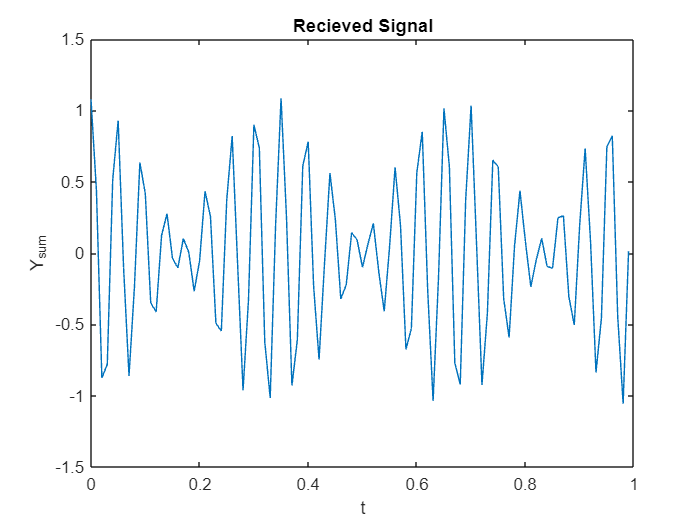

V1 = 180 / 3.6;
R1 = 250 * 1000;
td1 = 2 / C * R1;
fd1 = beta * V1;
alpha1 = 0.5;
y1 = alpha1 * cos(2 * pi * (fc + fd1) * (t - td1));
V2 = 216 / 3.6;
R2 = 200 * 1000;
td2 = 2 / C * R2;
fd2 = beta * V2;
alpha2 = 0.6;
y2 = alpha2 * cos(2 * pi * (fc + fd2) * (t - td2));
ySum = y1 + y2;
figure;
plot(t, ySum);
xlabel('t'); ylabel('Y_sum');
title('Recieved Signal');

#### 1 - 6)

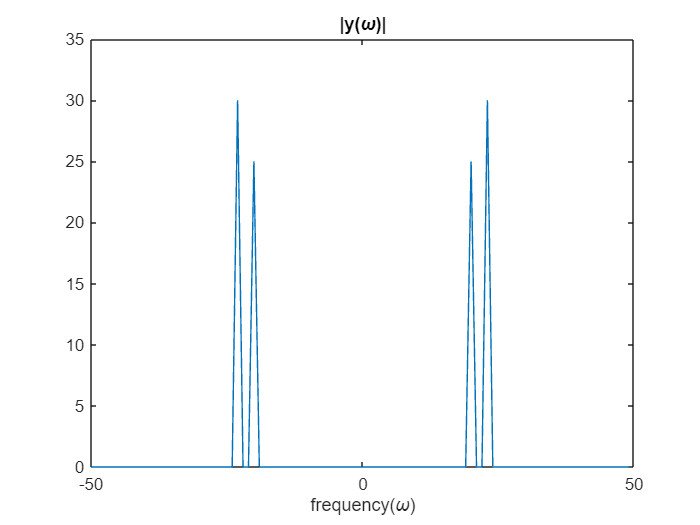

N = T * fs;
f = -fs/2 : fs/N : fs/2 - fs/N;
YSum = fftshift(fft(ySum));
figure;
plot(f, abs(YSum));
xlabel('frequency(\omega)');
title('|y(\omega)|')

[peak_values, primary_idx] = findpeaks(abs(YSum));
[~, peak_idxs] = sort(peak_values, 'descend');
fds = zeros(1,2);
tds = zeros(1,2);
YSum_phase = angle(YSum);
for i = 1:2
    pick_idx = primary_idx(peak_idxs(2 * (i - 1) + 1));
    fds(i) = abs(f(pick_idx)) - fc;
    tds(i) = abs(YSum_phase(pick_idx));
    tds(i) = tds(i) / (2 * pi * (fc + fds(i)));
    V_estimated = fds(i) / beta;
    R_estimated = tds(i) * C / 2;
    fprintf("R: %.1f Km, V: %.1f m/s, V: %.1f Km/H \n", R_estimated / 1000, V_estimated, V_estimated * 3.6);
end

R: 200.0 Km, V: 60.0 m/s, V: 216.0 Km/H 
R: 250.0 Km, V: 50.0 m/s, V: 180.0 Km/H 


#### 1 - 7)

V2 = 180 / 3.6;
R2 = 200 * 1000;
td2 = 2 / C * R2;
fd2 = beta * V2;
alpha2 = 0.6;
y2 = alpha2 * cos(2 * pi * (fc + fd2) * (t - td2));
ySum = y1 + y2;
YSum = fftshift(fft(ySum));

[peak_values, primary_idx] = findpeaks(abs(YSum));
[~, peak_idxs] = sort(peak_values, 'descend');
fds = zeros(1,2);
tds = zeros(1,2);
YSum_phase = angle(YSum);
for i = 1:2
    pick_idx = primary_idx(peak_idxs(2 * (i - 1) + 1));
    fds(i) = abs(f(pick_idx)) - fc;
    tds(i) = abs(YSum_phase(pick_idx));
    tds(i) = tds(i) / (2 * pi * (fc + fds(i)));
    V_estimated = fds(i) / beta;
    R_estimated = tds(i) * C / 2;
    fprintf("R: %.1f Km, V: %.1f m/s, V: %.1f Km/H \n", R_estimated / 1000, V_estimated, V_estimated * 3.6);
end

R: 222.7 Km, V: 50.0 m/s, V: 180.0 Km/H 
R: 3254.4 Km, V: 40.0 m/s, V: 144.0 Km/H 


#### 1 - 8)

V2 = 216 / 3.6;
R2 = 250 * 1000;
td2 = 2 / C * R2;
fd2 = beta * V2;
alpha2 = 0.6;
y2 = alpha2 * cos(2 * pi * (fc + fd2) * (t - td2));
ySum = y1 + y2;
YSum = fftshift(fft(ySum));

[peak_values, primary_idx] = findpeaks(abs(YSum));
[~, peak_idxs] = sort(peak_values, 'descend');
fds = zeros(1,2);
tds = zeros(1,2);
YSum_phase = angle(YSum);
for i = 1:2
    pick_idx = primary_idx(peak_idxs(2 * (i - 1) + 1));
    fds(i) = abs(f(pick_idx)) - fc;
    tds(i) = abs(YSum_phase(pick_idx));
    tds(i) = tds(i) / (2 * pi * (fc + fds(i)));
    V_estimated = fds(i) / beta;
    R_estimated = tds(i) * C / 2;
    fprintf("R: %.1f Km, V: %.1f m/s, V: %.1f Km/H \n", R_estimated / 1000, V_estimated, V_estimated * 3.6);
end

R: 250.0 Km, V: 60.0 m/s, V: 216.0 Km/H 
R: 250.0 Km, V: 50.0 m/s, V: 180.0 Km/H 


#### 1 - 9)

V2 = 216 / 3.6;
R2 = 200 * 1000;
td2 = 2 / C * R2;
fd2 = beta * V2;
alpha2 = 0.6;
y2 = alpha2 * cos(2 * pi * (fc + fd2) * (t - td2));

V3 = 360 / 3.6;
R3 = 110 * 1000;
td3 = 2 / C * R3;
fd3 = beta * V3;
alpha3 = 0.4;
y3 = alpha3 * cos(2 * pi * (fc + fd3) * (t - td3));

ySum = y1 + y2 + y3;
YSum = fftshift(fft(ySum));
threshold = 0.1;
[peak_values, primary_idx] = findpeaks(abs(YSum));
[peak_values, peak_idxs] = sort(peak_values, 'descend');
fds = [];
tds = [];
YSum_phase = angle(YSum);
for i = 1:floor(length(peak_idxs) / 2)
    if(peak_values(2 * (i - 1) + 1) < threshold)
        break;
    end
    peak_idx = primary_idx(peak_idxs(2 * (i - 1) + 1));
    fd = abs(f(peak_idx)) - fc;

    td = abs(YSum_phase(peak_idx));
    td = td / (2 * pi * (fc + fd));

    fds = [fds, fd];
    tds = [tds, td];
end
for i = 1:length(fds)
    V_estimated = fds(i) / beta;
    R_estimated = tds(i) * C / 2;
    fprintf("R: %.1f Km, V: %.1f m/s, V: %.1f Km/H \n", R_estimated / 1000, V_estimated, V_estimated * 3.6);
end

R: 200.0 Km, V: 60.0 m/s, V: 216.0 Km/H 
R: 250.0 Km, V: 50.0 m/s, V: 180.0 Km/H 
R: 110.0 Km, V: 100.0 m/s, V: 360.0 Km/H 
